# **Gas turbine simulation project Avans & Loughborough University**

This script is written as part of the aerospace engineering and maintenance minor project. The project was made possible by Lennart Nuhn from Avans university of applied sciences Breda and Bjorn Cleton from Loughborough University. It was carried out by the following 6 students:

**Mels Coremans, Geert Kock, Mart Nouws, Luca van Opdorp, Ivo van der Pas and Bas Viersma**

clc;
close all;
clear;

**General comments:**

- To run the script, please open the GUI file first.

- This version of the script includes the single and double spool gas turbine with and without bleed. 

- Inputs are done in the GUI.

- This script sends outputs to the GUI.

- Formulas in the script should not be changed.

**Declare fixed variables:**

Tb = 288.2;             % K
Lb = 0.0065;            % K/m
Pb = 101.325;           % kPa
hb = 0;                 % m
g = 9.80665;            % m/s^2
Mol = 0.0289644;        %
R1 = 8.3144598;         %
R = 287.5;              %

**Variables that are calculated when script is run:**

T0 = 0;        
P0 = 0;        
T1 = 0;
P1 = 0;
W1 = 0;
T2 = 0;
P2 = 0;
W2 = 0;
T21 = 0;
P21 = 0;
W21 = 0;
T3 = 0;
P3 = 0;
W3 = 0;
T31 = 0;
P31 = 0;
W31 = 0;
P4 = 0;
Q = 0;
W4 = 0;
WHPC = 0;
T41 = 0;
P41 = 0;
W41 = 0;
WLPC = 0;
T415 = 0;
P415 = 0;
W415 = 0;
T5 = 0;
P5 = 0;
W5 = 0;
Ps = 0;
Ts = 0;
Vj = 0;
rho = 0;
FN = 0;
SFC = 0;
ETATH = 0;
ETATH2 = 0;
ANeffective = 0;

**Run the Simulink model (GUIpm)**

sim('./Main/GUI_V5.slx');

%Request the input variables
engine_Type = ans.typeOfEngine;                 % 0=Single spool | 1=Double spool
bleed = ans.bleed;                              % 0=Yes | 1=No
poly_Isen = ans.polytropicIsentropic;           % Polytropic=0 | Isentropic=1

%Choose the Graphs
%Grap_Height_SFC = ans.GraphHeightSFC;          % 0=Dont show | 1=Show | Height against SFC
%Grap_Height_Thrust = ans.GraphHeightThrust;     % 0=Dont show | 1=Show | Height against Thrust
%Grap_Height_ETATH = ans.GraphHeightETATH;       % 0=Dont show | 1=Show | Height against ETATH

%Read the input values
Height = ans.height;                            %Height in meters
P3Q2_LPC = ans.PressureratioLPC;                %Pressure ratio low pressure compressor
P3Q2_HPC = ans.PressureratioHPC;                %Pressure ratio High pressure compressor
P_loss_Compressor = ans.pressureLossCompressor; %Pressure loss compressor
P_loss_Combuster = ans.pressureLossCombuster;   %Pressure loss combuster
W0 = ans.massFlow;                              %Mass flow ambient
LHV = ans.fuelCalorificValue;                   %fuelCalorificValue
y_t = ans.gammaTurbine;                         %Heat capacity(Gamma) ratio turbine
y_c = ans.gammaCompressor;                      %Heat capacity(Gamma) ratio compressor
Cp_hot = ans.CPTurbine;                         %Specific(CP) heat turbine
Cp_cold = ans.CPCompressor;                     %Specific(CP) heat compressor

ETHA_Comp = ans.Isentropiccompressor;           %Isentropic efficiency compressor
ETHA_Comb = ans.Isentropiccombuster;            %Isentropic efficiency combuster
ETHA_turb = ans.Isentropicturbine;              %Isentropic efficiency turbine
ETHA_Comp_Poly = ans.Polytropiccompressor;      %Polytropic efficiency compressor
ETHA_Comb_Poly = ans.Polytropiccombuster;       %Polytropic efficiency combuster
ETHA_turb_Poly = ans.Polytropicturbine;         %Polytropic efficiency turbine
T4 = ans.Temperaturecombustion;                 %Temperature after combustion
Bleed1 = 0.01;                                  %Bleed air from compressor to outlet     (%)
Bleed2 = 0.08;                                  %Bleed air from compressor to LPT        (%)
Bleed3 = 0.075;                                 %Bleed air from compressor to HPT        (%)
Bleed4 = 0.047;                                 %Bleed air to first LPT nozzle           (%)
Bleed5 = 0.033;                                 %Bleed air to second LPT nozzle          (%)
JetpipeP_loss = 0;                              %Pressure loss in jet pipe
IntakeP_loss = 0;                               %Pressure lpss at intake

if bleed == 1
    Bleed1 = 0;                                  
    Bleed2 = 0;                                  
    Bleed3 = 0;                                 
    Bleed4 = 0;                                 
    Bleed5 = 0;
end

**Functions**

[P0, T0] = AtmosphericCalc(Tb, Height, hb, Lb, Pb, g, Mol, R1);
[T1, P1, W1] = Inlet(T0, P0, W0);
[T2, P2, W2] = LPC_Inlet(T1, P1, W1, IntakeP_loss);
if engine_Type == 0
    [P3, T3, W3] = HPC_single(P2, T2, W2, P3Q2_LPC, y_c, ETHA_Comp, Bleed1, W0, P_loss_Compressor);
else
    [P21, T21, W21] = LPC(T2, P2, W2, P3Q2_LPC, y_c, ETHA_Comp);
    [P3, T3, W3] = HPC(P21, T21, W21, P3Q2_HPC, y_c, ETHA_Comp, Bleed1, W0, P_loss_Compressor);
end
[P31, T31, W31] = Combuster_Inlet(P3, T3, W3, Bleed2, Bleed3, W0);
[P4, W4, WF, FAR] = Combuster_Outlet(P31, T31, W31, ETHA_Comb, Bleed3, P_loss_Combuster, W0, T4);
if engine_Type == 0
    [T41, P41, W41] = HPT_Inlet(P4, T4, W4, Cp_hot, Bleed3, Cp_cold, T3, W0, Bleed4);
    [T5, P5, W5, WC, Expansion_ratio2] = LPT_Outlet_single(T41, P41, W41, W3, Cp_cold, T31, T2, Cp_hot, Bleed1, Bleed5, ETHA_turb, W4, W0);
else
    [T41, P41, W41] = HPT_Inlet(P4, T4, W4, Cp_hot, Bleed3, Cp_cold, T3, W0, Bleed4);
    [T415, P415, W415, Expansion_ratio1] = LPT_Inlet(T41, W41, P41, Cp_cold, T21, T3, Cp_hot, ETHA_turb, W0, Bleed1, Bleed5, W3, W4);
    [T5, P5, W5, WLPC, Expansion_ratio2] = LPT_Outlet(T415, P415, W3, Cp_cold, T21, T2, Cp_hot, ETHA_turb, W41, Bleed1, Bleed5, W0);
end
[T6, P6, W6] = Afterburner_calc(T5, P5, W5);
[T7, P7, W7] = Propelling_nozzle_inlet(T6, P6, W6, JetpipeP_loss);
[T8, P8, W8, Ps, Ts, VN, rho, ANeffective] = Propelling_nozzle_throat(T7, P7, W7, y_c, y_t, R);
[T9, P9, W9, UW] = Exhaust_calculations(T8, P8, W8, Cp_hot, P0, ETHA_turb);
[Vj, Fg_old, SFC, ETATH2, ETAPROP, TOTEFF, SFN, SPW, FG, FD, FN] = finalCalc(W0, WF, P0, y_c, R, ANeffective, Ps, Ts, UW, Cp_hot, T4, T3, W9);
%runImageScript(T9, engine_Type, T4, Tb);

%Send the output values back to the HMI
sim('./Main/GUI_V5.slx');

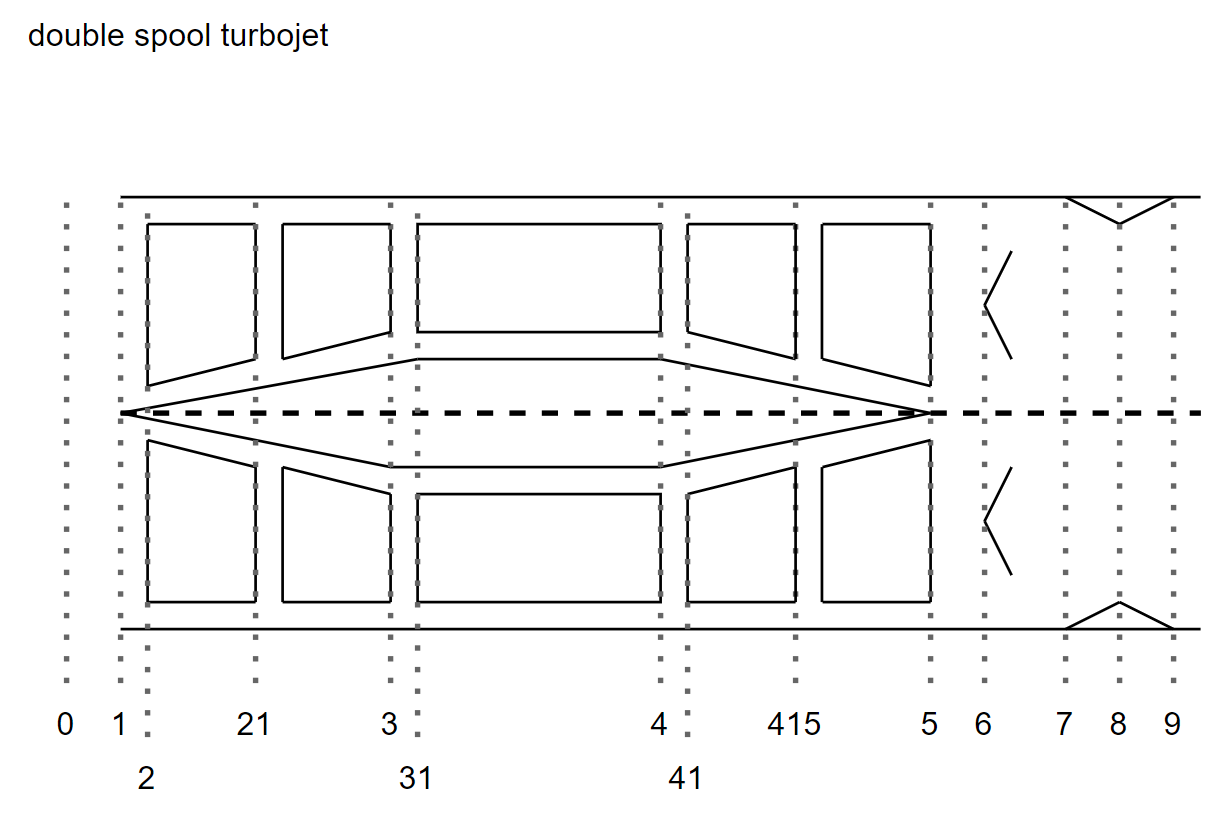

## **Extra code for simulating varying altitudes.**

h = linspace(0,15000,100);                                                    

[P0, T0] = AtmosphericCalc(Tb, h, hb, Lb, Pb, g, Mol, R1);
[T1, P1, W1] = Inlet(T0, P0, W0);
[T2, P2, W2] = LPC_Inlet(T1, P1, W1, IntakeP_loss);
if engine_Type == 0
    [P3, T3, W3] = HPC_single(P2, T2, W2, P3Q2_LPC, y_c, ETHA_Comp, Bleed1, W0, P_loss_Compressor);
else
    [P21, T21, W21] = LPC(T2, P2, W2, P3Q2_LPC, y_c, ETHA_Comp);
    [P3, T3, W3] = HPC(P21, T21, W21, P3Q2_HPC, y_c, ETHA_Comp, Bleed1, W0, P_loss_Compressor);
end
[P31, T31, W31] = Combuster_Inlet(P3, T3, W3, Bleed2, Bleed3, W0);
[P4, W4, WF, FAR] = Combuster_Outlet(P31, T31, W31, ETHA_Comb, Bleed3, P_loss_Combuster, W0, T4);
if engine_Type == 0
    [T41, P41, W41] = HPT_Inlet(P4, T4, W4, Cp_hot, Bleed3, Cp_cold, T3, W0, Bleed4);
    [T5, P5, W5, WC, Expansion_ratio2] = LPT_Outlet_single(T41, P41, W41, W3, Cp_cold, T31, T2, Cp_hot, Bleed1, Bleed5, ETHA_turb, W4, W0);
else
    [T41, P41, W41] = HPT_Inlet(P4, T4, W4, Cp_hot, Bleed3, Cp_cold, T3, W0, Bleed4);
    [T415, P415, W415, Expansion_ratio1] = LPT_Inlet(T41, W41, P41, Cp_cold, T21, T3, Cp_hot, ETHA_turb, W0, Bleed1, Bleed5, W3, W4);
    [T5, P5, W5, WLPC, Expansion_ratio2] = LPT_Outlet(T415, P415, W3, Cp_cold, T21, T2, Cp_hot, ETHA_turb, W41, Bleed1, Bleed5, W0);
end
[T6, P6, W6] = Afterburner_calc(T5, P5, W5);
[T7, P7, W7] = Propelling_nozzle_inlet(T6, P6, W6, JetpipeP_loss);
[T8, P8, W8, Ps, Ts, VN, rho, ANeffective] = Propelling_nozzle_throat(T7, P7, W7, y_c, y_t, R);
[T9, P9, W9, UW] = Exhaust_calculations(T8, P8, W8, Cp_hot, P0, ETHA_turb);
[Vj, Fg_old, SFC, ETATH2, ETAPROP, TOTEFF, SFN, SPW, FG, FD, FN] = finalCalc(W0, WF, P0, y_c, R, ANeffective, Ps, Ts, UW, Cp_hot, T4, T3, W9);

**Plots:**

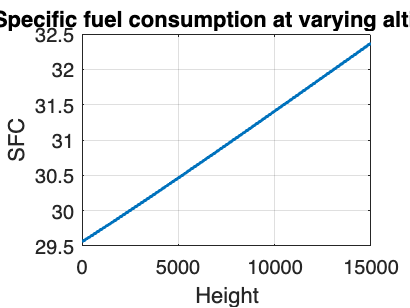

s1 = plot (h, SFC,LineWidth=1.5);
title('Specific fuel consumption at varying altitude')
xlabel('Height');
ylabel('SFC');
grid on;

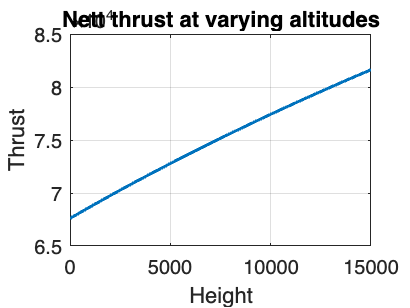


s2 = plot (h, FN,LineWidth=1.5);
title('Nett thrust at varying altitudes')
xlabel('Height');
ylabel('Thrust');
grid on;

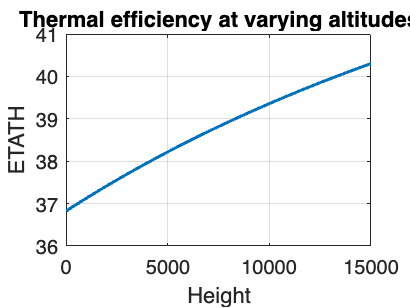


s3 = plot (h, ETATH2,LineWidth=1.5);
title('Thermal efficiency at varying altitudes')
xlabel('Height');
ylabel('ETATH');
grid on;

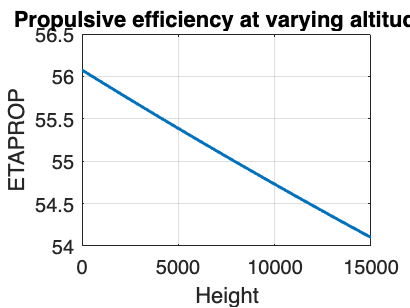


s4 = plot (h, ETAPROP,LineWidth=1.5);
title('Propulsive efficiency at varying altitudes')
xlabel('Height');
ylabel('ETAPROP');
grid on;

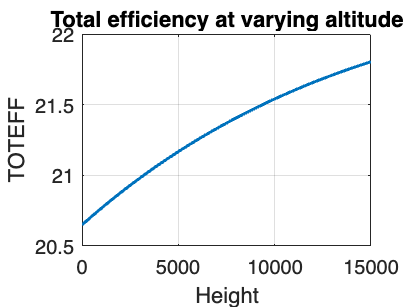


s5 = plot(h,TOTEFF,LineWidth=1.5);
title('Total efficiency at varying altitude')
xlabel('Height');
ylabel('TOTEFF');
grid on;

## **Extra code for simulating varying pressure ratios.**                

h = 12000;
P3Q2_LPC = linspace(0,12,13);                     
P3Q2_HPC = linspace(0,12,13); 

[P0, T0] = AtmosphericCalc(Tb, h, hb, Lb, Pb, g, Mol, R1);
[T1, P1, W1] = Inlet(T0, P0, W0);
[T2, P2, W2] = LPC_Inlet(T1, P1, W1, IntakeP_loss);
if engine_Type == 0
    [P3, T3, W3] = HPC_single(P2, T2, W2, P3Q2_LPC, y_c, ETHA_Comp, Bleed1, W0, P_loss_Compressor);
else
    [P21, T21, W21] = LPC(T2, P2, W2, P3Q2_LPC, y_c, ETHA_Comp);
    [P3, T3, W3] = HPC(P21, T21, W21, P3Q2_HPC, y_c, ETHA_Comp, Bleed1, W0, P_loss_Compressor);
end
[P31, T31, W31] = Combuster_Inlet(P3, T3, W3, Bleed2, Bleed3, W0);
[P4, W4, WF, FAR] = Combuster_Outlet(P31, T31, W31, ETHA_Comb, Bleed3, P_loss_Combuster, W0, T4);
if engine_Type == 0
    [T41, P41, W41] = HPT_Inlet(P4, T4, W4, Cp_hot, Bleed3, Cp_cold, T3, W0, Bleed4);
    [T5, P5, W5, WC, Expansion_ratio2] = LPT_Outlet_single(T41, P41, W41, W3, Cp_cold, T31, T2, Cp_hot, Bleed1, Bleed5, ETHA_turb, W4, W0);
else
    [T41, P41, W41] = HPT_Inlet(P4, T4, W4, Cp_hot, Bleed3, Cp_cold, T3, W0, Bleed4);
    [T415, P415, W415, Expansion_ratio1] = LPT_Inlet(T41, W41, P41, Cp_cold, T21, T3, Cp_hot, ETHA_turb, W0, Bleed1, Bleed5, W3, W4);
    [T5, P5, W5, WLPC, Expansion_ratio2] = LPT_Outlet(T415, P415, W3, Cp_cold, T21, T2, Cp_hot, ETHA_turb, W41, Bleed1, Bleed5, W0);
end
[T6, P6, W6] = Afterburner_calc(T5, P5, W5);
[T7, P7, W7] = Propelling_nozzle_inlet(T6, P6, W6, JetpipeP_loss);
[T8, P8, W8, Ps, Ts, VN, rho, ANeffective] = Propelling_nozzle_throat(T7, P7, W7, y_c, y_t, R);
[T9, P9, W9, UW] = Exhaust_calculations(T8, P8, W8, Cp_hot, P0, ETHA_turb);
[Vj, Fg_old, SFC, ETATH2, ETAPROP, TOTEFF, SFN, SPW, FG, FD, FN] = finalCalc(W0, WF, P0, y_c, R, ANeffective, Ps, Ts, UW, Cp_hot, T4, T3, W9);

**Plots:**

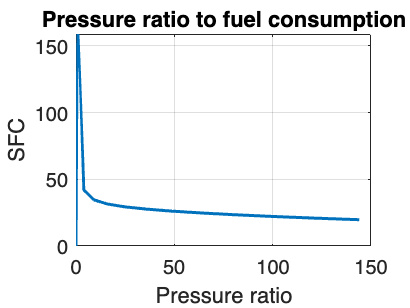

X1 = P3Q2_LPC.*P3Q2_HPC;
s1 = plot (X1, SFC,LineWidth=1.5);
title('Pressure ratio to fuel consumption');
xlabel('Pressure ratio');
ylabel('SFC');
grid on;

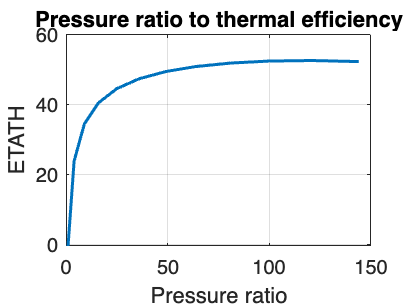


s3 = plot (X1, ETATH2,LineWidth=1.5);
title('Pressure ratio to thermal efficiency');
xlabel('Pressure ratio');
ylabel('ETATH');
grid on;

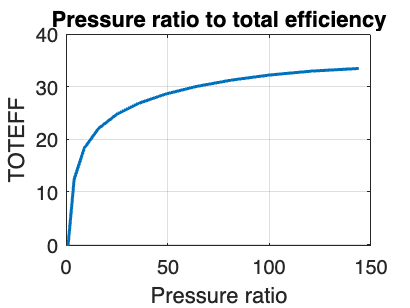


s5 = plot(X1,TOTEFF,LineWidth=1.5);
title('Pressure ratio to total efficiency');
xlabel('Pressure ratio');
ylabel('TOTEFF');
grid on;

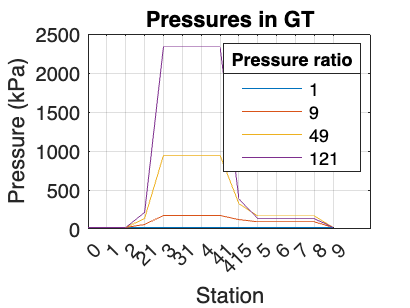


if engine_Type == 0
    Gx1 = 0:11;
    Gy1 = [P0(1,1),P1(1,1),P2(1,1),P3(1,2),P31(1,2),P4(1,2),P41(1,2),P5(1,2),P6(1,2),P7(1,2),P8(1,2),P9(1,1)];
else 
    Gx1 = 0:13;
    Gy1 = [P0(1,1),P1(1,1),P2(1,1),P21(1,2),P3(1,2),P31(1,2),P4(1,2),P41(1,2),P415(1,2),P5(1,2),P6(1,2),P7(1,2),P8(1,2),P9(1,1)];
end
plot(Gx1,Gy1);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Pressures in GT');
ylabel('Pressure (kPa)');
xlabel('Station');
grid on
hold on

if engine_Type == 0
    Gx2 = 0:11;
    Gy2 = [P0(1,1),P1(1,1),P2(1,1),P3(1,4),P31(1,4),P4(1,4),P41(1,4),P5(1,4),P6(1,4),P7(1,4),P8(1,4),P9(1,1)];
else 
    Gx2 = 0:13;
    Gy2 = [P0(1,1),P1(1,1),P2(1,1),P21(1,4),P3(1,4),P31(1,4),P4(1,4),P41(1,4),P415(1,4),P5(1,4),P6(1,4),P7(1,4),P8(1,4),P9(1,1)];
end
plot(Gx2,Gy2);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Pressures in GT');
ylabel('Pressure (kPa)');
xlabel('Station');
grid on
hold on

if engine_Type == 0
    Gx3 = 0:11;
    Gy3 = [P0(1,1),P1(1,1),P2(1,1),P3(1,8),P31(1,8),P4(1,8),P41(1,8),P5(1,8),P6(1,8),P7(1,8),P8(1,8),P9(1,1)];
else 
    Gx3 = 0:13;
    Gy3 = [P0(1,1),P1(1,1),P2(1,1),P21(1,8),P3(1,8),P31(1,8),P4(1,8),P41(1,8),P415(1,8),P5(1,8),P6(1,8),P7(1,8),P8(1,8),P9(1,1)];
end
plot(Gx3,Gy3);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Pressures in GT');
ylabel('Pressure (kPa)');
xlabel('Station');
grid on
hold on

if engine_Type == 0
    Gx4 = 0:11;
    Gy4 = [P0(1,1),P1(1,1),P2(1,1),P3(1,12),P31(1,12),P4(1,12),P41(1,12),P5(1,12),P6(1,12),P7(1,12),P8(1,12),P9(1,1)];
else 
    Gx4 = 0:13;
    Gy4 = [P0(1,1),P1(1,1),P2(1,1),P21(1,12),P3(1,12),P31(1,12),P4(1,12),P41(1,12),P415(1,12),P5(1,12),P6(1,12),P7(1,12),P8(1,12),P9(1,1)];
end
plot(Gx4,Gy4);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Pressures in GT');
ylabel('Pressure (kPa)');
xlabel('Station');
grid on
hold off
legend('1','9','49','121')
title(legend,'Pressure ratio')

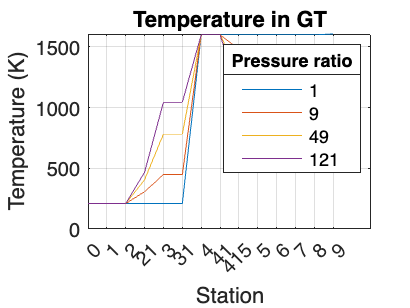


if engine_Type == 0
    Gx5 = 0:11;
    Gy5 = [T0(1,1),T1(1,1),T2(1,1),T3(1,2),T31(1,2),T4(1,1),T41(1,2),T5(1,2),T6(1,2),T7(1,2),T8(1,2),T9(1,2)];
else 
    Gx5 = 0:13;
    Gy5 = [T0(1,1),T1(1,1),T2(1,1),T21(1,2),T3(1,2),T31(1,2),T4(1,1),T41(1,2),T415(1,2),T5(1,2),T6(1,2),T7(1,2),T8(1,2),T9(1,2)];
end
plot(Gx5,Gy5);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Temperature in GT');
ylabel('Temperature (K)');
xlabel('Station');
grid on
hold on

if engine_Type == 0
    Gx6 = 0:11;
    Gy6 = [T0(1,1),T1(1,1),T2(1,1),T3(1,4),T31(1,4),T4(1,1),T41(1,4),T5(1,4),T6(1,4),T7(1,4),T8(1,4),T9(1,4)];
else 
    Gx6 = 0:13;
    Gy6 = [T0(1,1),T1(1,1),T2(1,1),T21(1,4),T3(1,4),T31(1,4),T4(1,1),T41(1,4),T415(1,4),T5(1,4),T6(1,4),T7(1,4),T8(1,4),T9(1,4)];
end
plot(Gx6,Gy6);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Temperature in GT');
ylabel('Temperature (K)');
xlabel('Station');
grid on
hold on

if engine_Type == 0
    Gx7 = 0:11;
    Gy7 = [T0(1,1),T1(1,1),T2(1,1),T3(1,8),T31(1,8),T4(1,1),T41(1,8),T5(1,8),T6(1,8),T7(1,8),T8(1,8),T9(1,8)];
else 
    Gx7 = 0:13;
    Gy7 = [T0(1,1),T1(1,1),T2(1,1),T21(1,8),T3(1,8),T31(1,8),T4(1,1),T41(1,8),T415(1,8),T5(1,8),T6(1,8),T7(1,8),T8(1,8),T9(1,8)];
end
plot(Gx7,Gy7);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Temperature in GT');
ylabel('Temperature (K)');
xlabel('Station');
grid on
hold on

if engine_Type == 0
    Gx8 = 0:11;
    Gy8 = [T0(1,1),T1(1,1),T2(1,1),T3(1,12),T31(1,12),T4(1,1),T41(1,12),T5(1,12),T6(1,12),T7(1,12),T8(1,12),T9(1,12)];
else 
    Gx8 = 0:13;
    Gy8 = [T0(1,1),T1(1,1),T2(1,1),T21(1,12),T3(1,12),T31(1,12),T4(1,1),T41(1,12),T415(1,12),T5(1,12),T6(1,12),T7(1,12),T8(1,12),T9(1,12)];
end
plot(Gx8,Gy8);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Temperature in GT');
ylabel('Temperature (K)');
xlabel('Station');
grid on
hold off
legend('1','9','49','121')
title(legend,'Pressure ratio')

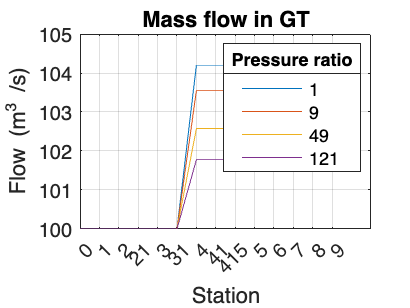


if engine_Type == 0
    Gx9 = 0:11;
    Gy9 = [W0(1,1),W1(1,1),W2(1,1),W3(1,1),W31(1,1),W4(1,2),W41(1,2),W5(1,2),W6(1,2),W7(1,2),W8(1,2),W9(1,2)];
else 
    Gx9 = 0:13;
    Gy9 = [W0(1,1),W1(1,1),W2(1,1),W21(1,1),W3(1,1),W31(1,1),W4(1,2),W41(1,2),W415(1,2),W5(1,2),W6(1,2),W7(1,2),W8(1,2),W9(1,2)];
end
plot(Gx9,Gy9);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Mass flow in GT');
ylabel('Flow (m^3/s)');
xlabel('Station');
grid on
hold on

if engine_Type == 0
    Gx10 = 0:11;
    Gy10 = [W0(1,1),W1(1,1),W2(1,1),W3(1,1),W31(1,1),W4(1,4),W41(1,4),W5(1,4),W6(1,4),W7(1,4),W8(1,4),W9(1,4)];
else 
    Gx10 = 0:13;
    Gy10 = [W0(1,1),W1(1,1),W2(1,1),W21(1,1),W3(1,1),W31(1,1),W4(1,4),W41(1,4),W415(1,4),W5(1,4),W6(1,4),W7(1,4),W8(1,4),W9(1,4)];
end
plot(Gx10,Gy10);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Mass flow in GT');
ylabel('Flow (m^3/s)');
xlabel('Station');
grid on
hold on

if engine_Type == 0
    Gx11 = 0:11;
    Gy11 = [W0(1,1),W1(1,1),W2(1,1),W3(1,1),W31(1,1),W4(1,8),W41(1,8),W5(1,8),W6(1,8),W7(1,8),W8(1,8),W9(1,8)];
else 
    Gx11 = 0:13;
    Gy11 = [W0(1,1),W1(1,1),W2(1,1),W21(1,1),W3(1,1),W31(1,1),W4(1,8),W41(1,8),W415(1,8),W5(1,8),W6(1,8),W7(1,8),W8(1,8),W9(1,8)];
end
plot(Gx11,Gy11);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Mass flow in GT');
ylabel('Flow (m^3/s)');
xlabel('Station');
grid on
hold on

if engine_Type == 0
    Gx11 = 0:11;
    Gy11 = [W0(1,1),W1(1,1),W2(1,1),W3(1,1),W31(1,1),W4(1,12),W41(1,12),W5(1,12),W6(1,12),W7(1,12),W8(1,12),W9(1,12)];
else 
    Gx11 = 0:13;
    Gy11 = [W0(1,1),W1(1,1),W2(1,1),W21(1,1),W3(1,1),W31(1,1),W4(1,12),W41(1,12),W415(1,12),W5(1,12),W6(1,12),W7(1,12),W8(1,12),W9(1,12)];
end
plot(Gx11,Gy11);
set(gca,'xtick',[0,1,2,3,4,5,6,7,8,9,10,11,12,13],'xticklabel',{'0','1','2','21','3','31','4','41','415','5','6','7','8','9'});
title('Mass flow in GT');
ylabel('Flow (m^3 /s)');
xlabel('Station');
grid on
hold off
legend('1','9','49','121')
title(legend,'Pressure ratio')

## **Station 0: Atmospheric calculations:**

In this station the ambient conditions are calculated. This is done by entering the height. The corresponding pressure is the output of the following formula: P0 = Pb * ((Tb - (h - hb) * Lb)/Tb).^((g * Mol)/(R1 * Lb)). In order to calculate the temperature the height is multiplied by a constant and then subtracted from the ambient temperature: T0 = Tb - (h * Lb).

function [P0, T0] = AtmosphericCalc(Tb, Height, hb, Lb, Pb, g, Mol, R1)
    P0 = Pb .* ((Tb - (Height - hb) .* Lb)./Tb).^((g * Mol)./(R1 .* Lb));    
    T0 = Tb - (Height .* Lb);                                              
end

## **Station 1: Inlet**

In the following code the temperature, pressure and flow of station 1 are defined. Station 1 is after intake and before the (first) compressor. If there is no turbofan present in the gasturbine, the previous mentioned variables are equivalent to the ambient conditions. If there is a turbofan, the pressure and temperature decrease. The flow remains the same. 

function [T1, P1, W1] = Inlet(T0, P0, W0)
    T1 = T0;                                                        % Temperature inlet is the same as ambient
    P1 = P0;                                                        % Pressure inlet is the same as ambient
    W1 = W0;                                                        % Nothing is added or taken from the mass flow at the inlet
end

## **Station 2: LPC (low pressure compressor) inlet**

In the following code the same variables as in the previous station are calculated. Since no energy and mass is added to the massflow the temperature and flow remain the same. If there is a pressure loss within the compressor inlet this can be calculated here.

function [T2, P2, W2] = LPC_Inlet(T1, P1, W1, IntakeP_loss)
    T2 = T1;                                                        % Temperature is constant between inlet and intake LPC.
    P2 = P1 .* (1 - IntakeP_loss);                                  % Calculates pressure difference in the case of a pressure loss at the intake. 
    W2 = W1;                                                        % Mass flow is constant between inlet and LPC intake.                            
end

## **Station 21: LPC**

Now that the massflow has left the first compression stage, the temperature and pressure have increased. This can be calculated by comparing the actual compression (isentropic) efficiency to the ideal compression. Firstly the temperature is calculated using the in going temperature, (isentropic) efficiency, pressure ratio and the heat capacity ratio of the compressor. Since nothing is added to the flow, it remains the same. If however bleed is taken in between 2 compression stages the flow is reduced. This is calculated by multiplying the bleed percentage with the mass flow and then subtracting it from the total mass flow.

**Formulas: **

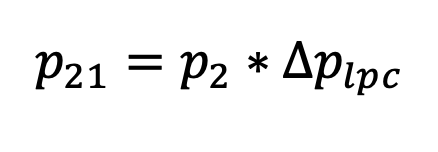        

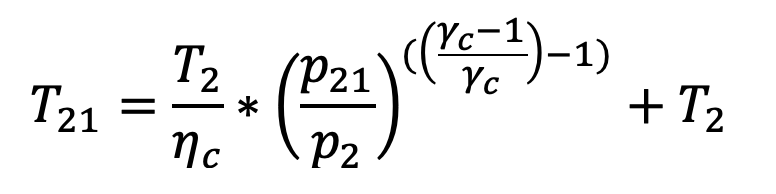                

function [P21, T21, W21] = LPC(T2, P2, W2, P3Q2_LPC, y_c, ETHA_Comp)
    P21 = P2 .* P3Q2_LPC;                                            % Pressure before LPC intake is multiplied with the compression ratio of the LPC.
    T21 = T2./ETHA_Comp .* (P3Q2_LPC.^((y_c-1)./y_c)-1) + T2;        % Temperature is calculated by comparing actual compression proces to the ideal proces. Compressing the mass flow results in increasing temperature since proces is not ideal.
    W21 = W2;                                                        % Mass flow is constant between LPC inlet and outlet.                        
end

## **Station 3: HPC (high pressure compressor) outlet**

If the gasturbine setup has a double spool the flow is compressed again. The calculations are the same as in the previous station. The compression ratio however can differ.

**Formulas:**

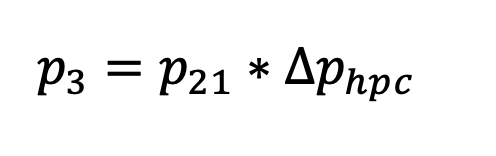

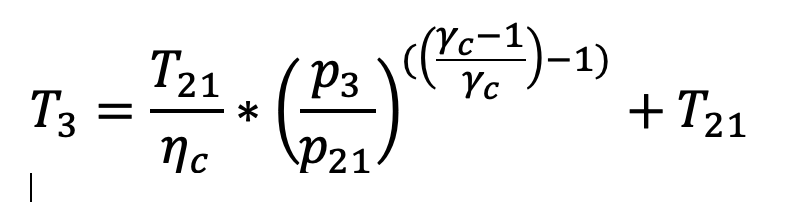

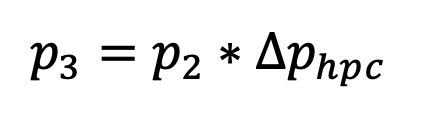

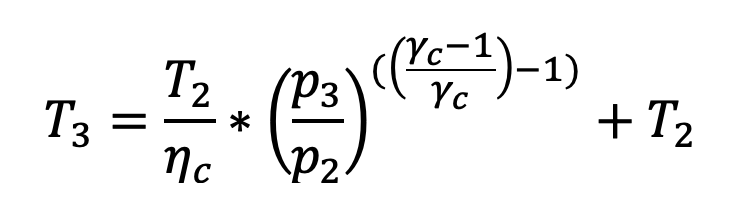

function [P3, T3, W3] = HPC(P21, T21, W21, P3Q2_HPC, y_c, ETHA_Comp, Bleed1, W0, CompressorP_loss)
    P3 = P21 .* P3Q2_HPC;                                            % Pressure before HPC intake is multiplied with the compression ratio of the HPC.
    T3 = (T21./ETHA_Comp) .* (P3Q2_HPC.^((y_c-1)./y_c)-1) + T21;     % Temperature is calculated by comparing actual compression proces to the ideal proces.
    W3 = W21 - (W0 .* Bleed1) - (W0 .* CompressorP_loss);            % Mass flow decreases if bleed is not 0.                           
end
function [P3, T3, W3] = HPC_single(P2, T2, W2, P3Q2_LPC, y_c, ETHA_Comp, Bleed1, W0, CompressorP_loss)
    P3 = P2 .* P3Q2_LPC;                                             % Pressure before compressor is multiplied with the compression ratio.
    T3 = (T2./ETHA_Comp) .* (P3Q2_LPC.^((y_c-1)./y_c)-1) + T2;       % Temperature is calculated by comparing actual compression proces to the ideal proces.
    W3 = W2 - (W0 .* Bleed1) - (W0 .* CompressorP_loss);             % Mass flow decreases if bleed is not 0.                          
end

## **Station 31 Combuster inlet**

After leaving the (second) compressor the flow enters the combustor. If there is a pressure loss betweed the compressor and the entry of the combustor this can be calculated here. If bleed is used the mass flow reduces. This can again be calculated by multiplying the bleed percentage with the mass flow and then subtracting it from the total mass flow.

function [P31, T31, W31] = Combuster_Inlet(P3, T3, W3, Bleed2, Bleed3, W0)
    T31 = T3;                                                       % Temperature is constant between compressor outlet and combuster inlet.
    P31 = P3;                                                       % Pressure is constant between compressor outlet and combuster inlet.
    W31 = W3 - (W0 .* Bleed2) - (W0 .* Bleed3);                     % Mass flow decreases due to bleed taken away before combuster inlet.
end

## **Station 4: Combustor outlet**

After leaving the combustor, temperature has increased significantly. The mass flow has also increased since fuel has been adden. In order to calculated this increase in flow, the fuel air ratio has to be calculated. When this is done the fuel flow is added to the total flow. The exiting temperature is a given variable since the gas turbine is designed with this specification. This means that only the pressure remains unknown. In a combustor the pressure remains the same, however a slight decrease can occur when the flow has to change directions. This pressure drop (if applicable) is a given variable and can be subtracted from the in going pressure.

function [P4, W4, WF, FAR] = Combuster_Outlet(P31, T31, W31, ETHA_Comb, Bleed3, P_loss_Combuster, W0, T4)
    P4 = P31 .* (1 - P_loss_Combuster);
    FAR1 = 0.10118 + 2.00376E-05.* (700 - T31);
    FAR2 = 3.7078E-03 - 5.2368E-06.* (700 - T31) - 5.2632E-06 .* T4;
    FAR3 = 8.889E-08 .* abs(T4 - 950);
    FAR = (FAR1 - sqrt(FAR1.^2 + FAR2) - FAR3)./ETHA_Comb;           % Fuel air ratio is calculated with the calculations above.
    WF = FAR .* W31;                                                 % Fuel flow is calculated by multiplying fuel air ratio with mass flow.
    W4 = W31 + WF + (W0 .* Bleed3);                                  % Mass flow increases when fuel is added.
end

## **Station 41: HPT (high pressure turbine) inlet**

Now that the mixture is combusted the flow arrives at the (high pressure) turbine. Depending on the gas turbine setup being single or double spool, the flow is expanded once or twice. When expanding the pressure and temperature decrease. The calculations are similar to the compressor calculations. First of all the pressure drop is calculated by multiplying the total pressure with the expansion ratio. If the expansion ratio is not given it can be derived by comparing the actual expansion to the ideal situation. The temperature is calculated with the work of the high pressure compressor. In a double spool gas turbine the high pressure compressor drives the high pressur turbine (similarily for the low pressure stages). If bleed is applicable the flow increases in this station since it is used for cooling the turbine fan blades.

**Formulas:**

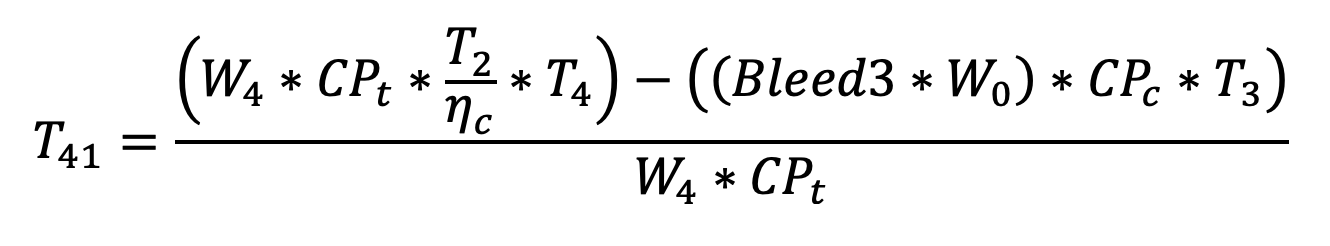

function [T41, P41, W41] = HPT_Inlet(P4, T4, W4, Cp_hot, Bleed3, Cp_cold, T3, W0, Bleed4)
    T41 = ((W4 .* Cp_hot .* T4)-((Bleed3 .* W0) .* Cp_cold .* T3)-((Bleed4 .* W0).*Cp_cold.*T3))./(W4 .* Cp_hot);               % Temperature is calculated when bleed is added to the burnt mixture. This is done by multiplying the temperatures of the bleed with the mass flow. Then dividing it by the flow and heat capacity in order to gain the temperature.
    P41 = P4;                                                                                                          % Pressure is constant between combuster outlet and turbine inlet.
    W41 = W4 + (W0 .* Bleed4);                                                                                          % Flow is calculated when bleed is added.                           
end

## **Station 415: LPT (low pressure turbine) inlet**

The inlet conditions of the low pressure turbine are equivalent to the exiting conditions of the combustor. If bleed is applicable this can be used here. With resulting flow increase and temperature drop.

**Formulas:**

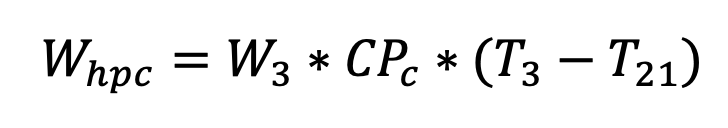

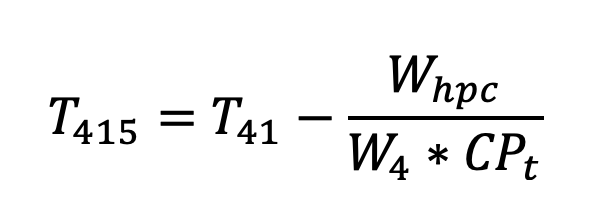

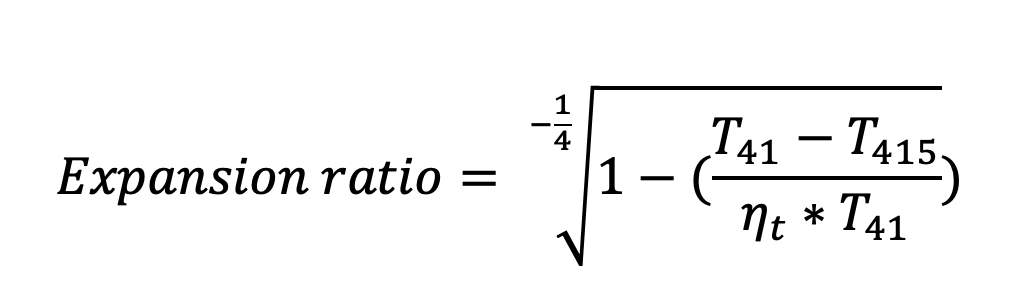

function [T415, P415, W415, Expansion_ratio1] = LPT_Inlet(T41, W41, P41, Cp_cold, T21, T3, Cp_hot, ETHA_turb, W0, Bleed1, Bleed5, W3, W4)
    WHPC = W3 .* Cp_cold .* (T3 - T21);                                     % Work of the high pressure compressor is calculated by multiplying the flow, heat capacity and temperature difference over the HPC.
    T415 = T41 - (WHPC./(W4.* Cp_hot));                                     % Temperature is calculated by subtracting the work divided by the flow and heat capacity from the exiting HPT temperature.
    Expansion_ratio1 = nthroot((1-(T41-T415)./(ETHA_turb*T41)),(-1/4));     % Expansion ratio is calculated by rewriting the temperature difference calculation over the HPT.
    P415 = P41./Expansion_ratio1;                                           % Pressure is calculated by dividing the ingoing pressure by the expansion ratio.
    W415 = W41 + (Bleed5 .* W0) + (Bleed1 .* W0);                           % Flow increases when cooling bleed is added in the HPT.                           
end

## **Station 5: LPT outlet **

The calculations of the low pressure turbine are similar to the high pressure stage. The only differences are the expansion ratio and no bleed being used in this stage.

**Formulas: **

function [T5, P5, W5, WC, Expansion_ratio2] = LPT_Outlet_single(T41, P41, W41, W3, Cp_cold, T31, T2, Cp_hot, Bleed1, Bleed5, ETHA_turb, W4, W0)
    WC = W3 .* Cp_cold .* (T31 - T2);                                       % Work of the low pressure compressor is calculated by multiplying the flow, heat capacity and temperature difference over the LPC.
    T5 = T41 - (WC./(W4 .* Cp_hot));                                        % Temperature is calculated by subtracting the work divided by the flow and heat capacity from the exiting LPT temperature.
    Expansion_ratio2 = nthroot((1-(T41-T5)./(ETHA_turb.*T41)),(-1/4));      % Expansion ratio is calculated by rewriting the temperature difference calculation over the LPT.
    P5 = P41./Expansion_ratio2;                                             % Pressure is calculated by dividing the ingoing pressure by the expansion ratio.
    W5 = W41 + (Bleed5 .* W0) + (Bleed1 .* W0);                             % Flow increases when cooling bleed is added in the LPT.
end
function [T5, P5, W5, WLPC, Expansion_ratio2] = LPT_Outlet(T415, P415, W3, Cp_cold, T21, T2, Cp_hot, ETHA_turb, W41, Bleed1, Bleed5, W0)
    WLPC = W3 .* Cp_cold .* (T21 - T2);                                     %  Work of the compressor is calculated by multiplying the flow, heat capacity and temperature difference over the compressor.
    T5 = T415 - (WLPC./(W41 .* Cp_hot));                                    % Temperature is calculated by subtracting the work divided by the flow and heat capacity from the exiting turbine temperature.
    Expansion_ratio2 = nthroot((1-(T415-T5)./(ETHA_turb.*T415)),(-1/4));    % Expansion ratio is calculated by rewriting the temperature difference calculation over the turbine.
    P5 = P415./Expansion_ratio2;                                            % Pressure is calculated by dividing the ingoing pressure by the expansion ratio.
    W5 = W41 + (Bleed5 .* W0) + (Bleed1 .* W0);                             % Flow increases when cooling bleed is added in the turbine.
end

## **Station 6: Afterburner calculations **

If applicable the afterburner calculations are done here.

function [T6, P6, W6] = Afterburner_calc(T5, P5, W5)
    T6 = T5;                                                                % Temperature remains the same since afterburner calculations are not implemented yet.
    P6 = P5;                                                                % Pressure remains the same since afterburner calculations are not implemented yet.
    W6 = W5;                                                                % Flow remains the same since afterburner calculations are not implemented yet.
end

## **Station 7: Propelling nozzle inlet**

If applicable the propelling nozle calculations are done here.

function [T7, P7, W7] = Propelling_nozzle_inlet(T6, P6, W6, JetpipeP_loss)
    T7 = T6;                                                                % Temperature remains the same since propelling nozle inlet calculations are not implemented yet.
    P7 = P6 .* (1-JetpipeP_loss);                                           % Pressure remains the same since propelling nozle inlet calculations are not implemented yet.
    W7 = W6;                                                                % Flow remains the same since propelling nozle inlet calculations are not implemented yet.
end

## **Station 8: Propelling nozzle throat:**

If applicable the propelling nozzle throat calculations are done here.

function [T8, P8, W8, Ps, Ts, VN, rho, ANeffective] = Propelling_nozzle_throat(T7, P7, W7, y_c, y_t, R)
    T8 = T7;                                                                % Temperature remains the same since propelling nozle throat calculations are not implemented yet.                                               
    P8 = P7;                                                                % Pressure remains the same since propelling nozle throat calculations are not implemented yet. 
    W8 = W7;                                                                % Flow remains the same since propelling nozle throat calculations are not implemented yet. 
    
    Ps = P7./(1 + (y_c - 1)./2).^(y_c./(y_c-1));                            % Static pressure is calculated 
    Ts = T7./(1 + (y_c - 1)./2);                                            % Static temperature is calculated
    VN = sqrt(y_t * R * Ts);                                                % Jett stream velocity is calculated                                                                             
    
    rho = (Ps.*1000)./(Ts.*R);                                              % Density of the jet stream is calculated
    ANeffective = W8./(VN.* rho);                                           % Effective nozzle area is calculated  
end

## **Station 9: Exhaust calculations: **

According to the gas turbine setup the exhaust calculations are the equivalent to the last stage being used.

function [T9, P9, W9, UW] = Exhaust_calculations(T8, P8, W8, Cp_hot, P0, ETHA_turb)
    P9 = P0 .* 1.02;                                                        % Pressure is calculated by multiplying the ambient pressure by 1.02
    T9 = T8-((ETHA_turb.*T8).*(1-(1./(P8./P9)).^0.25));                     % Temperature is calculated by subtracting the delta temperature when the pressure decreases
%   P9 = P8.*Ps;
    W9 = W8;                                                                % Mass flow remains the same
    UW = (T8-T9).*Cp_hot.*W9;                                               % Work over the exhaust is calculated
end

## **Final Calculations**

In this part the final calculations are done. Important outputs are given and used to graph simulations. Examples are: different thrusts, fuel consumption and efficiencies. These can be graphed against varying altitudes. If the script is adjusted, varying pressure ratios or varying combuster temperaturs can be used aswell.

function [Vj, Fg_old, SFC, ETATH2, ETAPROP, TOTEFF, SFN, SPW, FG, FD, FN] = finalCalc(W0, WF, P0, y_c, R, An, Ps, Ts, UW, Cp_hot, T4, T3, W9)
    Vj = sqrt(y_c * R *Ts);                                                 % Jett stream velocity is calculated
    Fg_old = (W0 + WF).* Vj + An.* (Ps - P0);                                           
    FG = (W9.* Vj) + An.* 1000.*(Ps - P0);	                                % Gross thrust calculation	        
    FD = W0 .* 250;                                                          							                
    FN = FG - FD;                                                           % Net thrust is calculated						                
    SFN = FG/W0;                                                            % Specific thrust is calculated                                          
    SFC = (WF./FG).* 1000000;                                               % Specific fuel consumption is calculated
    SPW = FN./W0;                                                           % Specific work is calculated                                           
    ETATH2 = 100*(UW./((T4-T3).*W0.*Cp_hot));                               % Thermal efficiency is calculated
    ETAPROP = 100*(2.*250)./(250+Vj);                                       % Propulsive efficiency is calculated                        
    TOTEFF = (ETATH2.*ETAPROP)./100;                                        % Total efficiency is calculated                       
end

## **Plots**

In this part plots are made visible. The input of the plots are values calculated in the final calculations part.

function calcPlots(h, SFC, Fn, ETATH)
    if Grap_Height_SFC == 1
           plot(h, SFC,LineWidth=1.5);
        title('Specific fuel consumption against varying altitudes')
        xlabel('Height');
        ylabel('SFC');
        grid on; 
    end
    if Grap_Height_Thrust == 1
          plot (h, Fn,LineWidth=1.5);
        title('Net thrust against varying altitudes')
        xlabel('Height');
        ylabel('Thrust');
        grid on;  
    end
    if Grap_Height_ETATH == 1
            plot (h, ETATH,LineWidth=1.5);
        title('Thermal efficiency against varying altitudes')
        xlabel('Height');
        ylabel('ETATH')
        grid on;
    end
end

**Foto's**

function runImageScript(T9, engine_Type, T4, Tb)
    save('image_data',"T9","engine_Type","T4", "Tb");
    run ./Main/Foto_script.mlx;
end